global row_vec

% Write your code here:
row_vec = [6 -2 12 0 4]

row_vec =      6    -2    12     0     4



%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(1))

Correct


global polyval_res

% Write your code here:
s = 2;
polyval_res = polyval(row_vec, s)

polyval_res = 132


%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(2))

Correct


global roots_of_poly

% Write your code here:
y = [1 -7 10]

y =      1    -7    10


roots_of_poly = roots(y)

roots_of_poly =      5
     2



%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(3))

Incorrect


global conv_res

% Write your code here:
y1 = [1 3]

y1 =      1     3


y2 = [1 2]

y2 =      1     2


y3 = [1 6]

y3 =      1     6



conv_res = conv(y1,y2)

conv_res =      1     5     6


conv_res = conv(conv_res, y3)

conv_res =      1    11    36    36



%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(4))

Correct


global deconv_res

% Write your code here:
z = [1 11 36 36]

z =      1    11    36    36


y = [1 6]

y =      1     6



deconv_res = deconv(z,y)

deconv_res =      1     5     6



%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(5))

Correct


global poly_res

% Write your code here:
r = [5 + 2*j 5 - 2*j]

r =    5.0000 + 2.0000i   5.0000 - 2.0000i


poly_res = poly (r)

poly_res =      1   -10    29



%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(6))

Correct


% Write your code here:
num = [16]

num = 16

den = [1 8 16]

den =      1     8    16



%Print the fraction using printsys()
printsys(num, den, 's')

 
num/den = 
 
         16
   --------------
   s^2 + 8 s + 16


a =16

a = 16

% Write your code here:
num = [16]

num = 16

den = [1 a 16]

den =      1    16    16


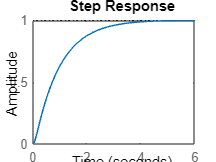


%Find the step reponse
step(num, den)


roots(den)

ans =   -14.9282
   -1.0718


% Write your code here:
num = [1 4]

num =      1     4


den = [2 5 3]

den =      2     5     3



%Convert the rational fraction into partial fraction.
[r, p, k] = residue(num, den)

r =    -2.5000
    3.0000


p =    -1.5000
   -1.0000



k =

     []




%Now convert the partial fraction back into rational function
[num, den] = residue(r, p, k)

num =     0.5000    2.0000


den =     1.0000    2.5000    1.5000


% Write your code here:
num = [2 10]

num =      2    10


den = [1 2 6]

den =      1     2     6



%Find the zeros, poles and gain using tf2zp.
[z, p, k] = tf2zp(num, den)

z = -5

p =   -1.0000 + 2.2361i
  -1.0000 - 2.2361i


k = 2

% Write your code here:
num = [1 5]

num =      1     5


den = [1 5 6]

den =      1     5     6


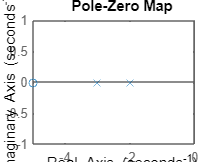


%Map the zeros and poles using pzmap.
pzmap(num, den)

% Write your code here:
z = [-2; -1]

z =     -2
    -1


p = [-1; -3; -4]

p =     -1
    -3
    -4


k = [5]

k = 5


%Find the transfer function using zp2tf().
[num, den] = zp2tf(z, p, k)

num =      0     5    15    10


den =      1     8    19    12


syms t
ft = t*cos(t)

$$ft = t\,\cos\left(t\right)$$


fs = laplace(ft)

$$fs = \frac{2\,s^{2}}{{\left(s^{2}+1\right)}^{2}}-\frac{1}{s^{2}+1}$$

ft = ilaplace(fs)

$$ft = t\,\cos\left(t\right)$$